# Image Processing Operator Approximation Using Deep Learning

Example from [mathworks.com](https://se.mathworks.com/help/images/image-processing-operator-approximation-using-deep-learning.html).

## Imports

For the bilateralFilterDataset function.

%import imbilatfilt
%import imwrite

## Directories

%imagesDir = tempdir;
imagesDir = 'D:\Projects\MasterThesis\Salsa_cryptanalysis\matlab\crypto_images\'

imagesDir = 'D:\Projects\MasterThesis\Salsa_cryptanalysis\matlab\crypto_images\'

subDir = 'images\'

subDir = 'images\'

% Add/remove '_small' at the end of images/preprocessedDataset, to
% make the dataset small (1000) or large (20000).
trainImagesDir = fullfile(imagesDir, subDir, 'CTs');
preprocessDataDir = fullfile(imagesDir, subDir, 'PTs');

## Download Training and Test Data

%imagesDir = tempdir;
%imagesDir = 'D:\Projects\MasterThesis\Salsa_cryptanalysis\matlab\models'
url_1 = 'http://www-i6.informatik.rwth-aachen.de/imageclef/resources/iaprtc12.tgz';
%downloadIAPRTC12Data(url_1,imagesDir);

% Use this when only wanting around 916 test images.
%trainImagesDir = fullfile(imagesDir,'iaprtc12','images','39');
%trainImagesDir = fullfile(imagesDir,'iaprtc12','images_small');

% Use this when wanting to use the full image data set.
%trainImagesDir = fullfile(imagesDir,'iaprtc12','images');

exts = {'.jpg','.bmp','.png'};
pristineImages = imageDatastore(trainImagesDir, 'FileExtensions',exts, 'IncludeSubfolders',true);

% Write out 
numel(pristineImages.Files)

ans = 1000

## Prepare Training Data

Process the data. DO NOT RUN!

%preprocessDataDir = [trainImagesDir filesep 'preprocessedDataset'];
%preprocessDataDir = fullfile(imagesDir, 'iaprtc12', 'preprocessedDataset');

%bilateralFilterDataset(pristineImages,preprocessDataDir);

%bilatFilteredImages = imageDatastore(preprocessDataDir,'FileExtensions',exts);

Load training images.

%preprocessDataDir = fullfile(imagesDir, 'iaprtc12', 'preprocessedDataset_small');
bilatFilteredImages = imageDatastore(preprocessDataDir, 'FileExtensions',exts, 'IncludeSubfolders',true);
numel(bilatFilteredImages.Files)

ans = 1000

## Define Random Patch Extraction Datastore for Training

bilatFilteredImages = imageDatastore(preprocessDataDir, 'FileExtensions',exts, 'IncludeSubfolders',true);

miniBatchSize = 1;
patchSize = [256 256];
dsTrain = randomPatchExtractionDatastore(pristineImages,bilatFilteredImages,patchSize, ....
    'PatchesPerImage',1);
dsTrain.MiniBatchSize = miniBatchSize;

%class(dsTrain)
inputBatch = read(dsTrain);
disp(inputBatch)

      InputImage        ResponseImage 
    _______________    _______________

    {256×256 uint8}    {256×256 uint8}



## Set Up Multiscale CAN Layers

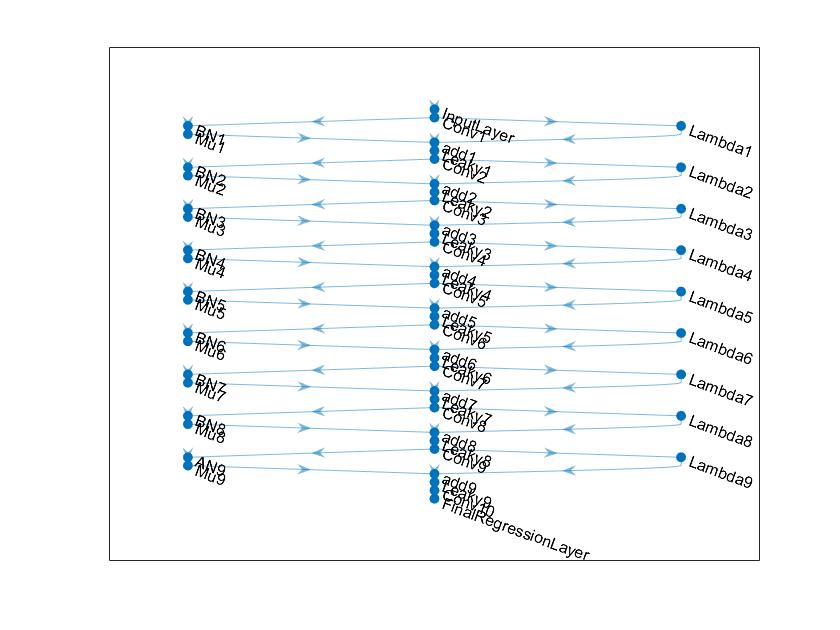

networkDepth = 10;
numberOfFilters = 32;
firstLayer = imageInputLayer([256 256 3],'Name','InputLayer','Normalization','none');


Wgts = zeros(3,3,3,numberOfFilters); 
for ii = 1:3
    % Denne kan lekes med (senere). Bygget for RGB-bilder.
    Wgts(2,2,ii,ii) = 1;
end
convolutionLayer = convolution2dLayer(3,numberOfFilters,'Padding',1, ...
    'Weights',Wgts,'Name','Conv1');


batchNorm = batchNormalizationLayer('Name','BN1');
adaptiveMu = adaptiveNormalizationMu(numberOfFilters,'Mu1');
addLayer = additionLayer(2,'Name','add1');
leakyrelLayer = leakyReluLayer(0.2,'Name','Leaky1');


middleLayers = [convolutionLayer batchNorm adaptiveMu addLayer leakyrelLayer];

Wgts = zeros(3,3,numberOfFilters,numberOfFilters);
for ii = 1:numberOfFilters
    Wgts(2,2,ii,ii) = 1;
end
    
for layerNumber = 2:networkDepth-2
    dilationFactor = 2^(layerNumber-1);
    padding = dilationFactor;
    conv2dLayer = convolution2dLayer(3,numberOfFilters, ...
        'Padding',padding,'DilationFactor',dilationFactor, ...
        'Weights',Wgts,'Name',['Conv' num2str(layerNumber)]);
    batchNorm = batchNormalizationLayer('Name',['BN' num2str(layerNumber)]);
    adaptiveMu = adaptiveNormalizationMu(numberOfFilters,['Mu' num2str(layerNumber)]);
    addLayer = additionLayer(2,'Name',['add' num2str(layerNumber)]);
    leakyrelLayer = leakyReluLayer(0.2, 'Name', ['Leaky' num2str(layerNumber)]);
    middleLayers = [middleLayers conv2dLayer batchNorm adaptiveMu addLayer leakyrelLayer];    
end


conv2dLayer = convolution2dLayer(3,numberOfFilters, ...
    'Padding',1,'Weights',Wgts,'Name','Conv9');

batchNorm = batchNormalizationLayer('Name','AN9');
adaptiveMu = adaptiveNormalizationMu(numberOfFilters,'Mu9');
addLayer = additionLayer(2,'Name','add9');
leakyrelLayer = leakyReluLayer(0.2,'Name','Leaky9');
middleLayers = [middleLayers conv2dLayer batchNorm adaptiveMu addLayer leakyrelLayer];


Wgts = sqrt(2/(9*numberOfFilters))*randn(1,1,numberOfFilters,3);
conv2dLayer = convolution2dLayer(1,3,'NumChannels',numberOfFilters, ...
    'Weights',Wgts,'Name','Conv10');


finalLayers = [conv2dLayer 
    regressionLayer('Name','FinalRegressionLayer')
];


layers = [firstLayer middleLayers finalLayers'];
lgraph = layerGraph(layers);


skipConv1 = adaptiveNormalizationLambda(numberOfFilters,'Lambda1');
skipConv2 = adaptiveNormalizationLambda(numberOfFilters,'Lambda2');
skipConv3 = adaptiveNormalizationLambda(numberOfFilters,'Lambda3');
skipConv4 = adaptiveNormalizationLambda(numberOfFilters,'Lambda4');
skipConv5 = adaptiveNormalizationLambda(numberOfFilters,'Lambda5');
skipConv6 = adaptiveNormalizationLambda(numberOfFilters,'Lambda6');
skipConv7 = adaptiveNormalizationLambda(numberOfFilters,'Lambda7');
skipConv8 = adaptiveNormalizationLambda(numberOfFilters,'Lambda8');
skipConv9 = adaptiveNormalizationLambda(numberOfFilters,'Lambda9');

lgraph = addLayers(lgraph,skipConv1);
lgraph = connectLayers(lgraph,'Conv1','Lambda1');
lgraph = connectLayers(lgraph,'Lambda1','add1/in2');

lgraph = addLayers(lgraph,skipConv2);
lgraph = connectLayers(lgraph,'Conv2','Lambda2');
lgraph = connectLayers(lgraph,'Lambda2','add2/in2');

lgraph = addLayers(lgraph,skipConv3);
lgraph = connectLayers(lgraph,'Conv3','Lambda3');
lgraph = connectLayers(lgraph,'Lambda3','add3/in2');

lgraph = addLayers(lgraph,skipConv4);
lgraph = connectLayers(lgraph,'Conv4','Lambda4');
lgraph = connectLayers(lgraph,'Lambda4','add4/in2');

lgraph = addLayers(lgraph,skipConv5);
lgraph = connectLayers(lgraph,'Conv5','Lambda5');
lgraph = connectLayers(lgraph,'Lambda5','add5/in2');

lgraph = addLayers(lgraph,skipConv6);
lgraph = connectLayers(lgraph,'Conv6','Lambda6');
lgraph = connectLayers(lgraph,'Lambda6','add6/in2');

lgraph = addLayers(lgraph,skipConv7);
lgraph = connectLayers(lgraph,'Conv7','Lambda7');
lgraph = connectLayers(lgraph,'Lambda7','add7/in2');

lgraph = addLayers(lgraph,skipConv8);
lgraph = connectLayers(lgraph,'Conv8','Lambda8');
lgraph = connectLayers(lgraph,'Lambda8','add8/in2');

lgraph = addLayers(lgraph,skipConv9);
lgraph = connectLayers(lgraph,'Conv9','Lambda9');
lgraph = connectLayers(lgraph,'Lambda9','add9/in2');


plot(lgraph)

## Specify Training Options

maxEpochs = 1;
initLearningRate = 0.00001; % Lek!
miniBatchSize = 1; % Iterasjoner = len(bilder) / miniBatchSize

options = trainingOptions('adam', ...
    'InitialLearnRate',initLearningRate, ...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize',miniBatchSize, ...
    'Plots','training-progress', ...
    'Verbose',true);

## Train the Network

doTraining = true;
if doTraining
    modelDateTime = datestr(now,'dd-mmm-yyyy-HH-MM-SS');
    net = trainNetwork(dsTrain,lgraph,options);
    save(['models/trainedOperatorLearning-' modelDateTime '-Epoch-' num2str(maxEpochs) '.mat'],'net');
else
    load('models/trainedOperatorLearning-Epoch-181.mat');
end

Error using trainNetwork (line 183)
The training images are of size 256x256x1 but the input layer expects images of size 256x256x3.

## Perform Bilateral Filtering Approximation Using Multiscale CAN

To process an image using a trained multiscale CAN network that approximates a bilateral filter, follow the remaining steps of this example. The remainder of the example shows how to:

- Create a sample noisy input image from a reference image.

- Perform conventional bilateral filtering of the noisy image using the [`imbilatfilt`](https://se.mathworks.com/help/images/ref/imbilatfilt.html) function.

- Perform an approximation to bilateral filtering on the noisy image using the CAN.

- Visually compare the denoised images from operator approximation and conventional bilateral filtering.

- Evaluate the quality of the denoised images by quantifying the similarity of the images to the pristine reference image.

## Create Sample Noisy Image

exts = {'.jpg','.png'};
fileNames = {'1000.png', '1025.png', '2310.png', '3040.png'};
filePath = [fullfile(matlabroot,'toolbox','images','imdata') filesep];
filePathNames = strcat(filePath,fileNames);
testImages = imageDatastore(filePathNames,'FileExtensions',exts);


montage(testImages)

% Select one of the images to use as the reference image for bilateral filtering. Convert the image to data type uint8.
indx = 3; % Index of image to read from the test image datastore
Ireference = readimage(testImages,indx);
Ireference = im2uint8(Ireference);

% Display the reference image.
imshow(Ireference)
title('Pristine Reference Image')

% Use the imnoise function to add zero-mean Gaussian white noise with a variance of 0.00001 to the reference image.
Inoisy = imnoise(Ireference,'gaussian',0.00001);
imshow(Inoisy)
title('Noisy Image')

## Filter Image Using Bilateral Filtering

degreeOfSmoothing = var(double(Inoisy(:)));
Ibilat = imbilatfilt(Inoisy,degreeOfSmoothing);
imshow(Ibilat)
title('Denoised Image Obtained Using Bilateral Filtering')

## Process Image Using Trained Network

Iapprox = activations(net,Inoisy,'FinalRegressionLayer');

% Image Processing Toolbox™ requires floating point images to have pixel values in the range [0, 1].
% Use the rescale function to scale the pixel values to this range, then convert the image to uint8.
Iapprox = rescale(Iapprox);
Iapprox = im2uint8(Iapprox);
imshow(Iapprox)
title('Denoised Image Obtained Using Multiscale CAN')

## Visual and Quantitative Comparison

roi = [300 30 50 50];

% Crop the images to this ROI, and display the result as a montage.
montage({imcrop(Ireference,roi),imcrop(Inoisy,roi), ...
    imcrop(Ibilat,roi),imcrop(Iapprox,roi)}, ...
    'Size',[1 4]);
title('Reference Image | Noisy Image | Bilateral-Filtered Image | CAN Prediction');


% PSNR
% The larger the better.
noisyPSNR = psnr(Inoisy,Ireference);
bilatPSNR = psnr(Ibilat,Ireference);
approxPSNR = psnr(Iapprox,Ireference);
disp(['PSNR of: Noisy Image / Bilateral-Filtered Image / Operator Approximated Image = ', ...
    num2str([noisyPSNR bilatPSNR approxPSNR])])

% SSIM
% The closer to 1, the better.
noisySSIM = ssim(Inoisy,Ireference);
bilatSSIM = ssim(Ibilat,Ireference);
approxSSIM = ssim(Iapprox,Ireference);
disp(['SSIM of: Noisy Image / Bilateral-Filtered Image / Operator Approximated Image = ', ...
    num2str([noisySSIM bilatSSIM approxSSIM])])

% NIQE
% The lower the better.
noisyNIQE = niqe(Inoisy);
bilatNIQE = niqe(Ibilat);
approxNIQE = niqe(Iapprox);
disp(['NIQE score of: Noisy Image / Bilateral-Filtered Image / Operator Approximated Image = ', ...
    num2str([noisyNIQE bilatNIQE approxNIQE])])